# Section A

## Q1

i)

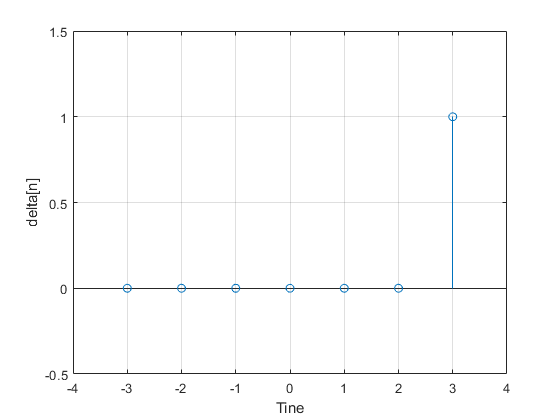

delta = @(x) (1)*(x==0);
t = (-3:3);
stem(t, delta(t-3))
axis([-4 4 -.5 1.5]);
grid on;
ylabel("delta[n]");
xlabel("Tine");

ii)

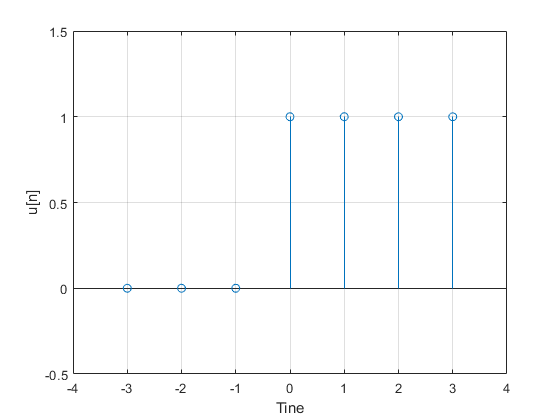

step = @(x) (1)*(x>0);
stem(t, step(t+1))
axis([-4 4 -.5 1.5]);
grid on;
ylabel("u[n]");
xlabel("Tine");

iii)

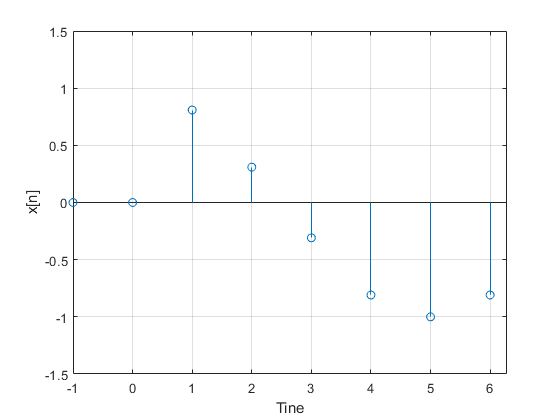

x = @(n) cos(n*pi/5).*step(n);
t = (-1:(2*pi));
stem(t, x(t))
axis([-1 (2*pi) -1.5 1.5]);
grid on;
ylabel("x[n]");
xlabel("Tine");

iv) This signal has been time shifted to the right by an interval of 3

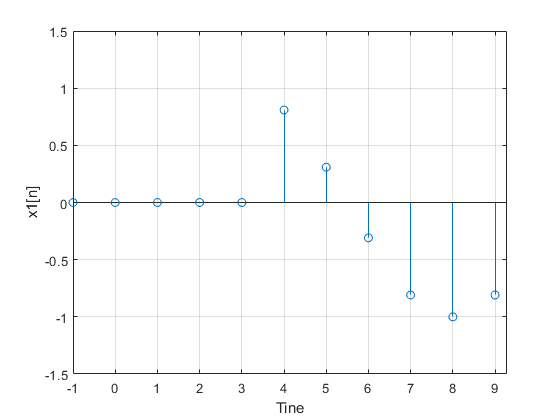

x1 = @(n) x(n-3);
t = (-1:(2*pi)+3);
stem(t, x1(t))
axis([-1 (2*pi)+3 -1.5 1.5]);
grid on;
ylabel("x1[n]");
xlabel("Tine");

v) This signal has been mirrored/inverted about the x axis

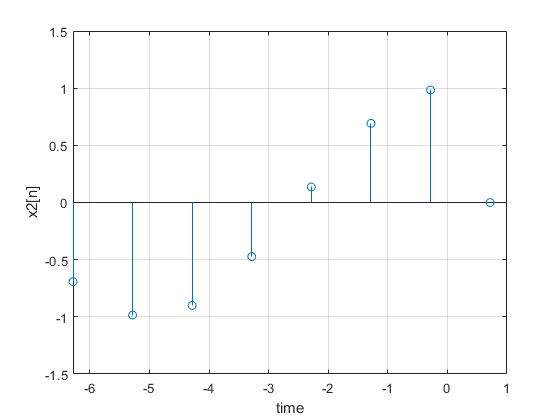

x2 = @(n) x(-n);
t = (-(2*pi):1);
stem(t, x2(t))
axis([-(2*pi) 1 -1.5 1.5]);
grid on;
ylabel("x2[n]");
xlabel("time");

### Q2

i)

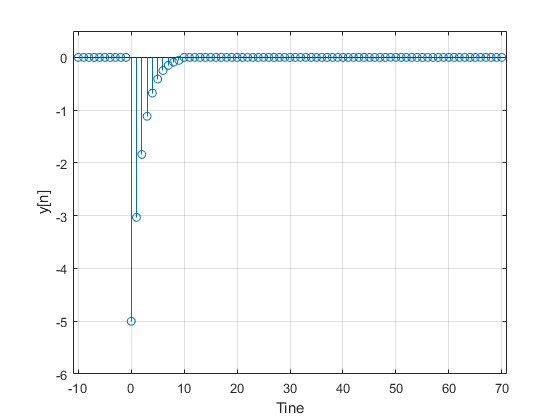

t = (-10:70);
u = @(n) 1*(n<0);
y = @(n) 5.*exp(-n/2).*(u(n) - u(n-10));
stem(t, y(t));
axis([-11 71 -6 0.5]);
grid on;
ylabel("y[n]");
xlabel("Tine");

ii)This signal has been subjected to time shrinking by a factor of 3

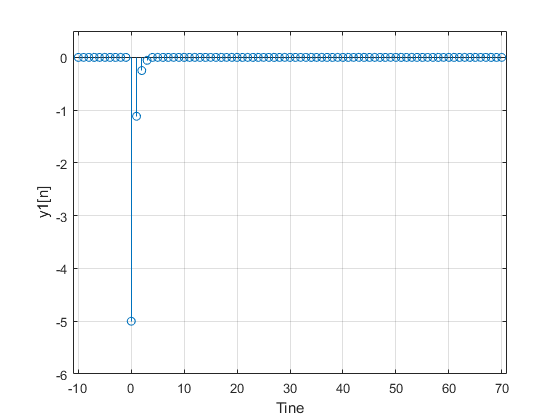

y1 = @(n) y(3*n);
stem(t, y1(t));
axis([-11 71 -6 0.5]);
grid on;
ylabel("y1[n]");
xlabel("Tine");

iii)This signal has been subjected to time stretching by a factor of 3

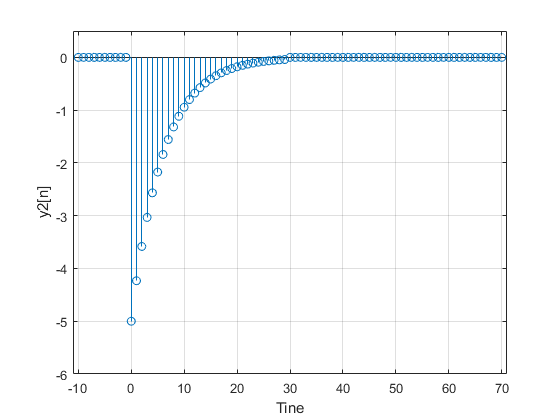

y2 = @(n) y(n/3);
stem(t, y2(t));
axis([-11 71 -6 0.5]);
grid on;
ylabel("y2[n]");
xlabel("Tine");

### Q3

z = @(n) 5.*exp(-n/2).*(u(n) - u(n-10));
y3 = @(T) z(T/3);

t = (-10:0.1:70);
n = (-10:70);

i) The signal plotted below is the continuous time signal $y_{3}(t)=z(\frac{t}{3}) $

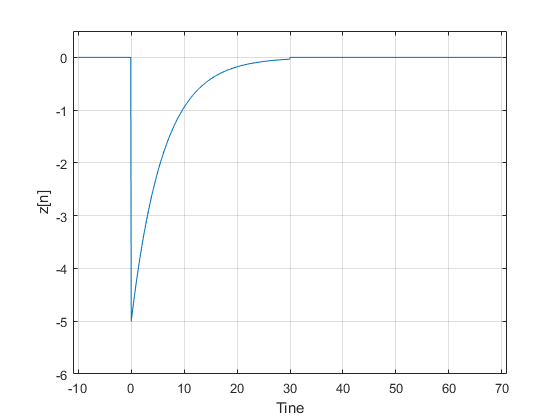

plot(t, z(t/3));
axis([-11 71 -6 0.5]);
grid on;
ylabel("z[n]");
xlabel("Tine");

ii) As you can see below, the signals $y_{2}[n]$ and $y_{3}[n]$ are identical. What is supposed to be demonstrated in this question is; if we sample the original continuous signal and then perfrom a time stretch or shrink operation as opposed to the transformed continous signal and then performing sampling, what happens? 

Likely, the values from the signal that you sample and then transform will differ from transforming and then sampling, meaning we are beginning to lose precision and accuracy to our original signal. This also makes intuitive sense if we sample a signal we have a bounded range of values that the signal can take and then perform the transform it will also be bound, but if we take the sample after tranformation, the transform is unaffected by the bounded range of values.

Also it is likely that result that is supposed to occur isn't happening because I programmed it incorrectly

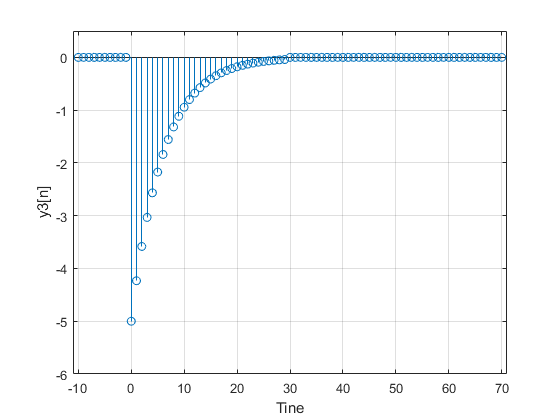

stem(n, y3(n));
axis([-11 71 -6 0.5]);
grid on;
ylabel("y3[n]");
xlabel("Tine");

stem(n, y2(n));
axis([-11 71 -6 0.5]);
grid on;
ylabel("y2[n]");
xlabel("Tine");

## Section B

Note that in this portion of the lab the first month of the year is $n=2
$

### 1)

This is the difference equation solved for $y[n]$:


$$y[n] = (x[n]+y[n-1])*1.02$$


monthly input = $100

initial balance = $2000

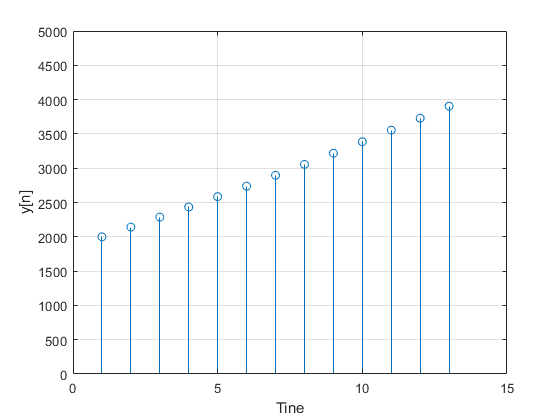

x = @(n) n;
y0 = 2000;
y = @(x, y1) (x + y1)*1.02;

yn1 = zeros(12,1);
yn1(1) = y0;

for t = 2:13    
    yn1(t) = y(x(100), yn1(t-1));%100$ per month + 2
end

stem(yn1);
axis([0 15 0 5000]);
grid on;
ylabel("y[n]");
xlabel("Tine");

### 2)

monthly input = $0

initial balance = $2000

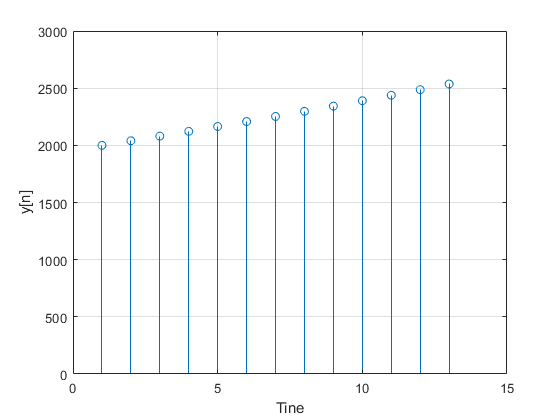

yn2 = zeros(12,1);
yn2(1) = y0;
for t = 2:13    
    yn2(t) = y(x(0), yn2(t-1));
end

stem(yn2);
axis([0 15 0 3000]);
grid on;
ylabel("y[n]");
xlabel("Tine");

### 3)

monthly input = $100n

Where n is the number of the month from a starting date.

initial balance = $2000

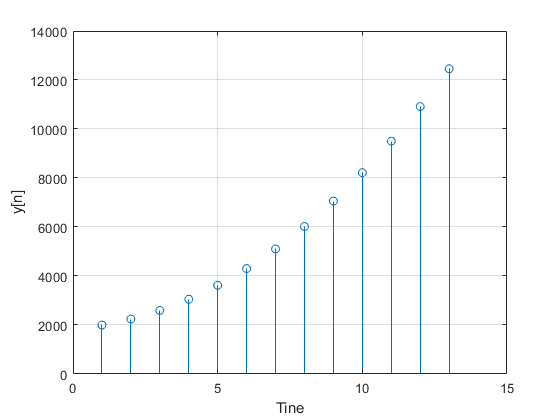

yn3 = zeros(12,1);
yn3(1) = y0;
for t = 2:13    
    yn3(t) = y(x(100*t-1), yn3(t-1));
end


stem(yn3);
axis([0 15 0 14000]);
grid on;
ylabel("y[n]");
xlabel("Tine");

## Section C

### 1) I know the manual said use Matlabs MAX function, I glossed over that and made my own:

### 2)

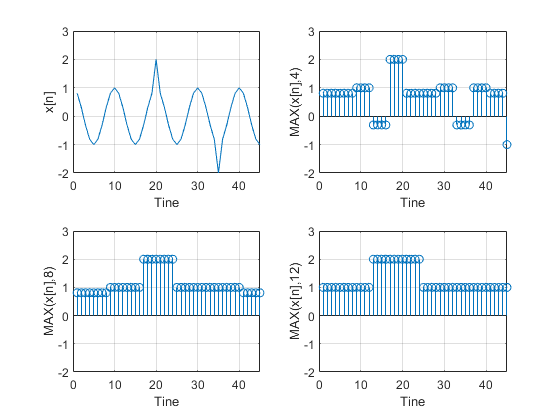

xc = @(T) cos(pi*T/5) + delta(T - 20) - delta(T - 35);
t = (1:45);

yc_4 = MAX_FILTER(xc(t), 4);
yc_8 = MAX_FILTER(xc(t), 8);
yc_12 = MAX_FILTER(xc(t), 12);

subplot(2,2,1);
plot(t,xc(t));
axis([0 45 -2 3]);
grid on;
ylabel("x[n]");
xlabel("Tine");

subplot(2,2,2);
stem(yc_4);
axis([0 45 -2 3]);
grid on;
ylabel("MAX(x[n],4)");
xlabel("Tine");

subplot(2,2,3);
stem(yc_8);
axis([0 45 -2 3]);
grid on;
ylabel("MAX(x[n],8)");
xlabel("Tine");

subplot(2,2,4);
stem(yc_12);
axis([0 45 -2 3]);
grid on;
ylabel("MAX(x[n],12)");
xlabel("Tine");

### 3)

The value of N dictates how many centering points there are in a signal, if we have a signal with 50 points, and N = 2 then we will have 25 centering points, if N = 5, there will be 10 centering points. What this implies for our system is that as we increase the N we begin to the original resolution of our signal. This type of filter would be used for reducing the size of an image, for exmaple a 255 x 255 pixel image with a N=2 max filter, technically reproduces a 125x125 images becuase the largest values in a square of 4 pixels is spread across those 4 pixels. 

## Section D

### 1) Below is the functions that I created for Power and Energy calculations, it was simpler to do them as two seperate equations

t = (1:10);
POWER(t);
ENERGY(t);

### 2) 

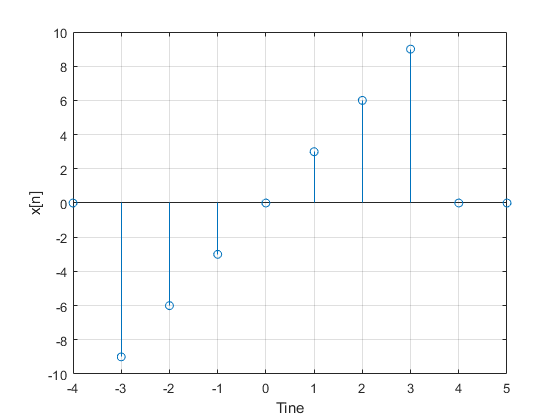

x = @(n) -3*(u(n+3) - u(n-4)).*n;
t = (-4:5);
subplot(1,1,1)
stem(t,x(t));
axis([-4 5 -10 10]);
grid on;
ylabel("x[n]");
xlabel("Tine");

POWER(x(t))

ans = 12.6000

ENERGY(x(t))

ans = 252

The power of the signal is $P_{x}=12.6 W
$ and the energy is $E_{x} = 252J$

## Appendix/Functions

function [OUT] = MAX_FILTER(x,N)
    len = length(x);
    OUT = zeros(len,1);
    OUT = x;
    for t = 1:N:len
        largest = x(t);
        for n = t:t+N%find the largest value for every n points
            if n < len && x(n) > largest
                largest = x(n);
            end
        end
        if n < len
            OUT(t:t+N) = largest;%set the largest value across the range of t-N:t
        else
            OUT(t:len) = largest;
        end
    end
    
end 

function [p] = POWER(x)
   len = length(x);
   hold = zeros(len,1);
   hold = abs(x).^2;
   p = (1/(2*len))*sum(hold);
end

function [e] = ENERGY(x)
   len = length(x);
   hold = zeros(len,1);
   hold = abs(x).^2;
   e = sum(hold);
end